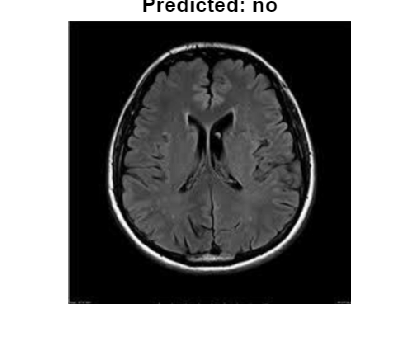

clc;
clear;
close all;

%% Step 1: Load Trained Model
load('brain_tumor_resnet18_model.mat', 'netTransfer');  % Update filename if needed

%% Step 2: Load and Preprocess Test Image
imgPath = 'C:\Users\rahul\OneDrive\Desktop\dataset\tumor_image2.png'; % <- Change this to your test image
img = imread(imgPath);

% If grayscale, convert to RGB
if ndims(img) == 2
    img = repmat(img, [1 1 3]);
elseif size(img, 3) == 1
    img = cat(3, img, img, img);
end

% Resize to match ResNet-18 input
inputSize = netTransfer.Layers(1).InputSize;
imgResized = imresize(img, inputSize(1:2));

% Convert to datastore for classification
augImg = augmentedImageDatastore(inputSize(1:2), imgResized, ...
    'ColorPreprocessing', 'none');

%% Step 3: Classify Image
predictedLabel = classify(netTransfer, augImg);

%% Step 4: Display Result
imshow(img);
title(['Predicted: ', char(predictedLabel)], 'FontSize', 16);

fprintf('Predicted Class: %s\n', string(predictedLabel));

Predicted Class: no
